# Examples

clear;

## Solvent properties

Properties of a pure solvent

% Properties of methanol
MeOH = solvents.Methanol

MeOH =   Methanol with properties:

       molarmass: 32.0400
    viscosity20C: 5.7093e-04
    viscosity25C: 5.2648e-04
      density20C: 792.3440
      density25C: 787.7270



% Get a property (e.g., viscosity at 20 ºC)
MeOH_visc = MeOH.viscosity20C

MeOH_visc = 5.7093e-04


% Calculate water density at 23 ºC
T = 23 + 273.12;
H2O_dens = solvents.Water.calcDensityDIPPR105(T)

H2O_dens = 1.0002e+03


% Calculate acetonitrile viscosity at 23 ºC
ACN_visc = solvents.Acetonitrile.calcViscosityVogel(T)

ACN_visc = 3.5124e-04

Properties of a 90/10 %v/v Methanol/Water mixture at 22 ºC

% Pure solvents
MeOH = solvents.Methanol;
H2O = solvents.Water;

% Mixture volume fractions
vMeOH = 0.90;
vH2O = 0.10;

% Calculate viscosity using mixing rule
T = 22 + 273.12;  % K
MeOH_H2O_visc = solvents.viscMixingRuleLog(T, vMeOH, MeOH, vH2O, H2O);  % Pa s
MeOH_H2O_visc = MeOH_H2O_visc * 1000  % cP or mPa s

MeOH_H2O_visc = 0.6169

## Pressure drop through a column

Calculate the pressure drop in a 210 mm x 4 mm, 5 um column, and using methanol as mobile phase. 

% Operating conditions and column
Q = 1 / 1e6 / 60;  % m/s, flowrate
epsilon = 0.4;  % porosity
Dc = 4 / 1000;  % m, column diameter
L = 210 / 1000;  % m, column length
dp = 5 / 1e6;  % m, particle diameter
T = 22 + 273.15;  % K, ambient temperature

% Solvent (methanol) properties
visc = solvents.Methanol.calcViscosityVogel(T);
dens = solvents.Methanol.calcDensityDIPPR105(T);

% Calculate pressure drop
deltaP = pressureDrop.deltaPFromFlowrateErgun(Q, visc, dens, epsilon, dp, Dc, L);  % Pa s

% Convert to bar
deltaP = deltaP / 1e5  % bar

deltaP = 51.9521

Calculate the maximum allowed flowrate for 30 bar of pressure drop. Same column as above.

max_deltaP = 30 * 1e5;  % Pa, pressure drop
Q = pressureDrop.flowrateFromDeltaPErgun(max_deltaP, visc, dens, epsilon, dp, Dc, L);  % flowrate in m/s
Q = Q * 1e6 * 60  % flowrate in ml/min

Q = 0.5775

## Calculate SMB flowrates by mass balance

From any four known flowrates, calculate the remaining ones by mass balance

% Set known flowrates as a structure 
% Field names must be four of the set: 'Q1', 'Q2', 'Q3', 'Q4', 'QE', 'QX', 'QF', 'QR'
knownQ.QE = 2;
knownQ.QF = 1;
knownQ.QX = 1.5;
knownQ.Q1 = 3;
% Solve the mass balance
[~, allQ] = smb.flowrates(knownQ)

allQ = struct with fields:
    QE: 2
    QF: 1
    QX: 1.5000
    Q1: 3
    Q2: 1.5000
    Q3: 2.5000
    Q4: 1
    QR: 1.5000


## Triangle theory

Plot the triangular separation region for SMB following the Triangle Theory framework.

### Linear isotherm

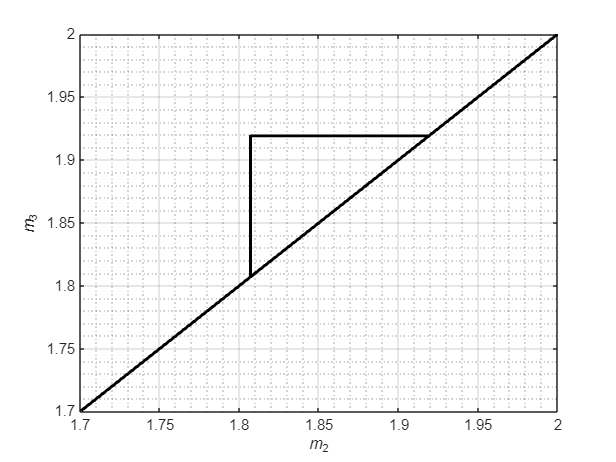

H = [1.8070, 1.9191];

figure()
triangleTheory.plotLinearSepRegion(H)

### Langmuir isotherm

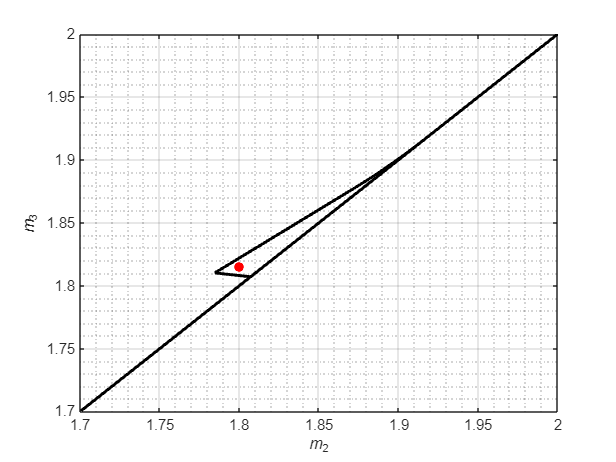

Q = [17.544	17.606];  % Langmuir isotherm constant Q (capacity)
b = [0.103	0.109];  % Langmuir isotherm constant b (b1 < b2)
Cfeed = [1.5 0.5];  % feed concentration

% Add an operation point
m2m3 = [1.800, 1.815];

figure()
triangleTheory.plotLangmuirSepRegion(Q, b, Cfeed, m2m3)